%% Define F(z) and G(z) here:
function y = PHI3(z)
    % y = (1i ./ 2) + (0 .* z);
    % y = 1i .* z .* (z .* z - 1);
    y = 1i .* z .* (1 + z + z .* z);
end

function y = G(z)
    % y = exp(z);
    % y = 1 + z;
    % y = 1 + z + z .^ 2 / 2;
    % y = 1 + z + z .^ 2 / 2 + z .^ 3 / 6;
    % y = 1 + z + z .^ 2 / 2 + z .^ 3 / 6 + z .^ 4 / 24;
    % y = 1 + z + z .^ 2 / 2 + z .^ 3 / 6 + z .^ 4 / 24 + z .^ 5 / 120;
    % y = 1 + z + z .^ 2 / 2 + z .^ 3 / 6 + z .^ 4 / 24 + z .^ 5 / 120 + z .^ 6 / 720;
    % y = 1 + z + z .^ 2 / 2 + z .^ 3 / 6 + z .^ 4 / 24 + z .^ 5 / 120 + z .^ 6 / 720 + z .^ 7 / 5040;
    % y = (z .* z - 1) ./ z;
    y = z;
end

%% Set the boundary of the parameters here:
% Umin = -3;
% Umax = 3;
% Vmin = 0;
% Vmax = 2;

Umin = -4;
Umax = 4;
Vmin = 0;
Vmax = 4;
U = Umin : 0.1 : Umax;
V = Vmin : 0.1 : Vmax;

% U = linspace(Umin, Umax);
% V = linspace(Vmin, Vmax);

[u, v] = meshgrid(U, V);

X_1 = arrayfun(@(x, y) x_1(x, y), u, v);

X_2 = arrayfun(@(x, y) x_2(x, y), u, v);

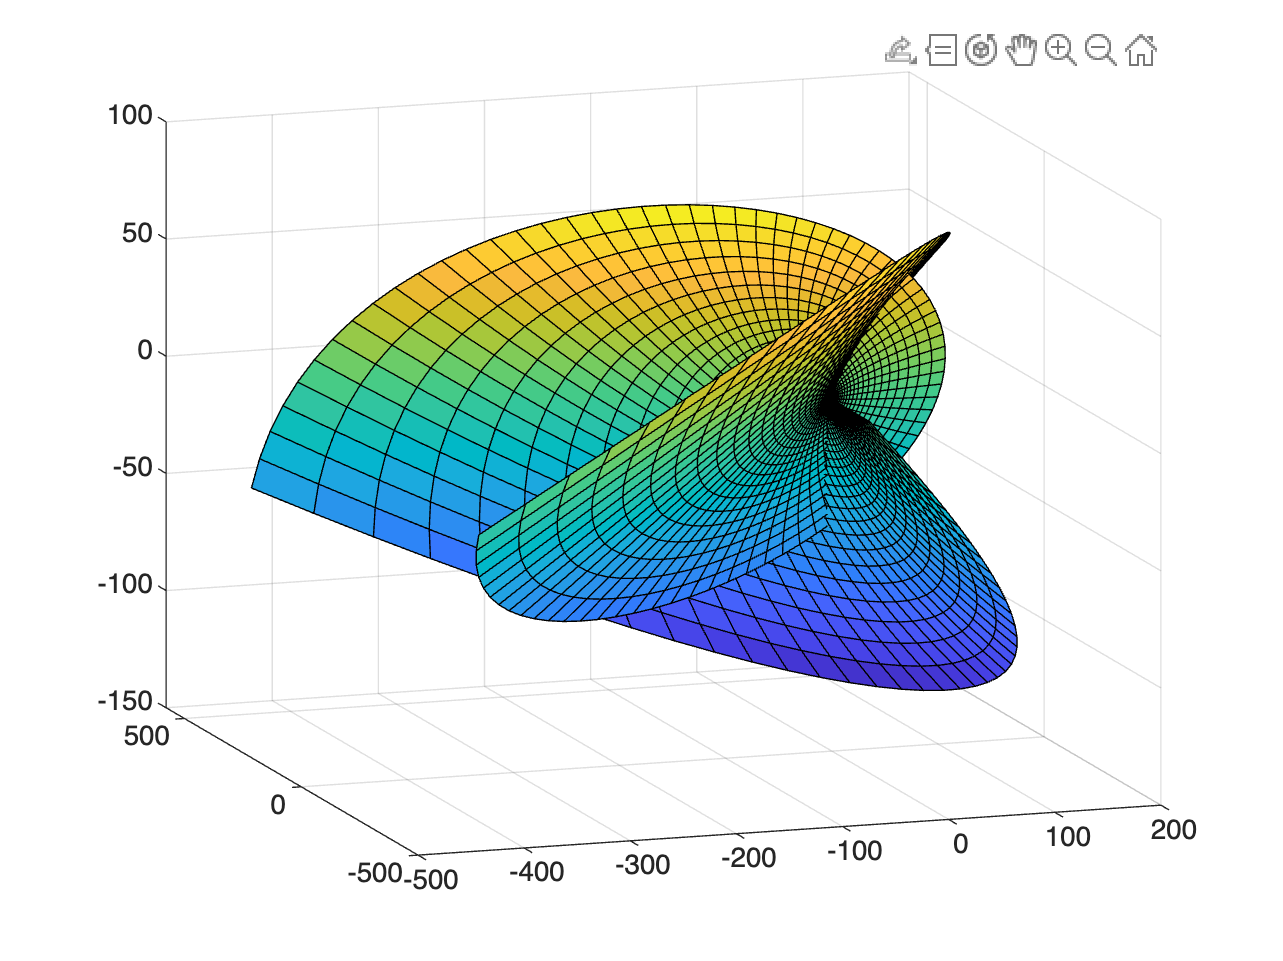

S =   Surface with properties:

       EdgeColor: [0 0 0]
       LineStyle: '-'
       FaceColor: 'flat'
    FaceLighting: 'flat'
       FaceAlpha: 1
           XData: [41x81 double]
           YData: [41x81 double]
           ZData: [41x81 double]
           CData: [41x81 double]

  Show all properties


X_3 = arrayfun(@(x, y) x_3(x, y), u, v);

S = surf(X_1, X_2, X_3)


% saveas(gcf, "Enneper.png")

% Total_K = Total_Curvature(@F, @G, 0, Inf, -Inf, Inf)
% function Total_K = Total_Curvature(f, g, Umin, Umax, Vmin, Vmax)
%     g_prime = diff(g);
%     K = @(x, y) - (4 .* abs(g_prime(u + 1i .* v)) ./ abs(f(u + 1i .* v) .* (1 + abs(g(u + 1i .* v) .^ 2)) .^ 2)) .^ 2;
%     Total_K = integral2(K, Umin, Umax, Vmin, Vmax);
% end

function y = x_1(u, v)
    y = real(integral(phi_1(u, v), 0, 1));
end

function y = x_2(u, v)
    y = real(integral(phi_2(u, v), 0, 1));
end

function y = x_3(u, v)
    y = real(integral(phi_3(u, v), 0, 1));
end

function y = phi_1(u, v)
    y = @(t) 1 ./ 2 .* PHI3((u + 1i .* v) .* t) .* (1 ./ G((u + 1i .* v) .* t) - G((u + 1i .* v) .* t)) .* (u + 1i .* v);
end

function y = phi_2(u, v)
    y = @(t) 1i ./ 2 .* PHI3((u + 1i .* v) .* t) .* (1 ./ G((u + 1i .* v) .* t) + G((u + 1i .* v) .* t)) .* (u + 1i .* v);
end

function y = phi_3(u, v)
    y = @(t) PHI3((u + 1i .* v) .* t) .* (u + 1i .* v);
end
